# Practical 8

## Question Form - Part 1

Phthalic Anhydride (PA) is industrially produced by the oxidation of the o-xylene on V2O5 – TiO2  catalyst. The o-xylene diluted in air is fed to a multi tubular fixed bed reactor cooled by the circulation of  a molten salts. Details of the configuration, catalysts, and operating conditions are given below. The  reaction network is given by the following three reactions: 


$$\begin{array}{l}
C_6 H_4 {\left({\mathrm{CH}}_3 \right)}_2 +3O_2 \to C_6 H_4 {\left(\mathrm{CO}\right)}_2 O+3H_2 O\;\;\left(1\right)\;\;\;\;\;\;\;\;\Delta H=-1285409\;\frac{\mathrm{kJ}}{\mathrm{kmol}}\\
C_6 H_4 {\left({\mathrm{CH}}_3 \right)}_2 +10\ldotp 5O_2 \to 8{\mathrm{CO}}_2 +5H_2 O\;\;\;\;\;\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\Delta H=-4564000\;\frac{\mathrm{kJ}}{\mathrm{kmol}}\\
C_6 H_4 {\left(\mathrm{CO}\right)}_2 O++7\ldotp 5O_2 \to 8{\mathrm{CO}}_2 +2H_2 O\;\;\;\;\left(3\right)\;\;\;\;\;\;\;\;\;\;\Delta H=-327859\;\frac{\mathrm{kJ}}{\mathrm{kmol}}
\end{array}$$


The system can be considered a mixture of ideal gases. Adopting a 1D heterogeneous model with the heat  transfer computed through the Dixon-Specchia correlation, assess: 

- the number of tubes needed considering the constraints reported in the data.

- the thermal profile along the tube. 

- the conversion of C6H4(CH3)2 and the selectivity of C6H4(CO)2O along the tube. 

## Theory

The material balance in heterogeneous model is written as follows:


$$\begin{array}{l}
\sum_{j=1}^{\mathrm{NR}} \nu_{i,j} \gamma_j \;{\mathrm{MW}}_i \;\left(1-\varepsilon \right)\rho_{\mathrm{cat}} +k\left(\rho_{i,g} -\rho_{i,s} \right)a_V =0\;\left(\mathrm{In}\;\mathrm{catalytic}\;\mathrm{site}\right)\\
-\frac{d\dot{m} }{\mathrm{dV}}+k_1 \left(\rho_{i,s} -\rho_{i,g} \right)a_V =0\;\left(\mathrm{in}\;\mathrm{gas}\;\mathrm{phase}\right)
\end{array}$$


The second equation is ODE, but the first equation is algebric. Thus, we have an DAE system.

The energy balance in heterogeneous model is written as follows:


$$\begin{array}{l}
-m\hat{C_p } \frac{\mathrm{dT}}{\mathrm{dV}}+h\left(T_s -T\right)a_V +U\left(T_{\mathrm{ext}} -T\right)a_V =0\;\left(\mathrm{in}\;\mathrm{gas}\;\mathrm{phase}\right)\\
m\hat{C_p } \frac{\mathrm{dT}}{\mathrm{dV}}+\sum_{j=1}^{\mathrm{NR}} \gamma_j \Delta \tilde{H} \left(1-\varepsilon \right)\rho_{\mathrm{cat}} +h\left(T-T_s \right)a_V =0\;\;\;\left(\mathrm{in}\;\mathrm{catalytic}\;\mathrm{site}\right)
\end{array}$$
 

The third term refers to external heat transfer coefficient.

We have to define mass matrix. The diagonal values in the matrix represent the equation which have derivative forms, and the values are assigned to 1. The other values are assigned to 0 (?). 

## Initial Data

close all, clear, clc
global Stoichiometry deltaH mw SpecificHeatP Viscosity0 ...
    TubeDiameter CatalystDensity ...
    VoidFraction MoltenSaltsTemperature G ParticleDiameter NS NR lambda0 ...
    lambda_cat ReactorLength TubeThickness lambdaTube ExternalHeatCoefficient
global diffusivity0 a_v_particle NEQ
Stoichiometry=[0 -3 -1 1 +3 0
               0 -10.5 -1 0 5 8
               0 -7.5 0 -1 2 8];
deltaH=[-1285409 -4564000 -3278591]; %kJ/kmol

mw=[28 32 106.16 148.12 18 44]; %kg/kmol
SpecificHeatP=0.992; %kJ/kg/K
Viscosity0=2.95e-5; %Pa*s
NS = 6;
NR = 3;

%-Reactor:
TubeDiameter=0.0254; %m
ParticleDiameter=0.005; %m
ReactorLength=3; %m
CatalystDensity=2100; %kg/m3
DiameterRatio=TubeDiameter/ParticleDiameter;
VoidFraction=0.363+0.35*(exp(-0.39*DiameterRatio));

ExternalHeatCoefficient=700; %W/m2/K
TubeThickness=0.0012; %m
lambdaTube=20; %W/m/K 
lambda0=4.78e-2; % W/m/K
lambda_cat=1.5; %W/m/K

diffusivity0 = [8.31e-05, 7.02e-05, 2.58e-05, 2.22e-05, 8.98e-05, 2.02e-05];
a_v_particle = 6/ParticleDiameter*(1-VoidFraction);

## Operating Conditions

MoltenSaltsTemperature=335+273.15; %K
FeedTemperature=MoltenSaltsTemperature;
G=4900; %kg/m2/h
oXylToAirRatio=0.013;
n_in=[0.79 0.21 oXylToAirRatio 0 0 0]; %moles
ntot_in = sum(n_in);
for i = 1:NS
    MolarFractionIN(i) = n_in(i)/ntot_in;
end
FeedPressure=1.3; %bar
basis_calc=1; %kmol
for i=1:NS
    mass(i)=MolarFractionIN(i)*basis_calc*mw(i); %kg
end
mtot = sum(mass);

for i = 1:NS
    MassFractionIN(i) = mass(i)/mtot;
end
NEQ = 2*NS+2+1; 
M = zeros(NEQ,NEQ);
for i = 1:(NS+1)
    M(i,i) = 1;
end
M(NEQ,NEQ) = 1; % pressure

## Solve ODE 

options = odeset('Mass',M,'AbsTol',1e-06,'RelTol',1e-06);

[t,y]=ode15s(@pfr_het,[0:0.001:ReactorLength], ...
    [MassFractionIN FeedTemperature ...
    MassFractionIN FeedTemperature FeedPressure],options);

## Post Processing

NP=length(t);

Across=pi*TubeDiameter^2/4; %m2

for j=1:NP
    for i=1:NS
        n(j,i)=G*Across*y(j,i)/mw(i); % kmol/h
    end
    MolarFraction(j,:)=n(j,:)./sum(n(j,:));
end

%conversion o-xylene:
for j=1:NP
    conv_o_xyl(j)=(n(1,3)-n(j,3))/(n(1,3));
end

%selectivity to PA:
for j=1:NP
    sel_PA(j)=n(j,4)/(n(1,3)-n(j,3)+1e-12);
end

%yield:
for j=1:NP
    yield(j)=conv_o_xyl(j)*sel_PA(j);
end

%productivity: kg_PA/ut in the tube
for j=1:NP
    productivity_tube(j)=yield(j)*n(1,3)*mw(4);
end

target = 8000; % Ton/year
n_tubes = target*1e3/(365*24)*1/productivity_tube(end);
disp("number of tubes: "+ n_tubes)

number of tubes: 11665.3669


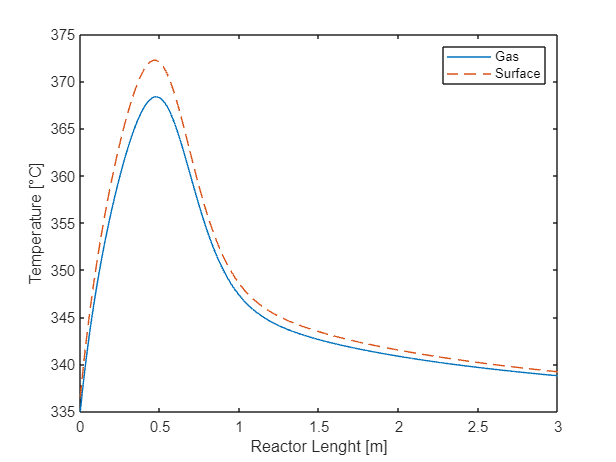


figure(1)
plot(t,y(:,7)-273.15)
hold on
plot(t,y(:,end-1)-273.15,'Linestyle','--')
xlabel('Reactor Lenght [m]')
ylabel('Temperature [°C]')
legend('Gas','Surface')

What is the cause of difference between gas phase and catalyst surface? The catalyst surface is hotter than gas (because of an exothermic reaction), and gas tries to remove heat from surface. Because of heat transfer limitations, there's a difference between two plots. The difference between psuodo homogeneous and heterogeneous model temperature profile isn't for operating conditions, hence the internal limitaion is playing a key role!

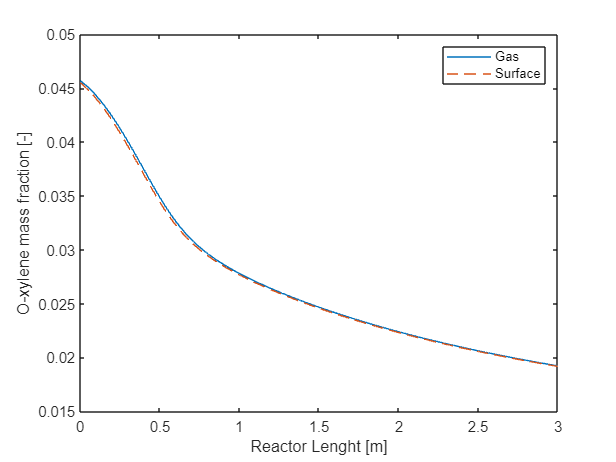

figure(2)
plot(t,y(:,3))
hold on
plot(t,y(:,3+7),'linestyle','--')
xlabel('Reactor Lenght [m]')
ylabel('O-xylene mass fraction [-]')
legend('Gas','Surface')

## Jalal's Notes

As mentioned in the question we want to produce PA from the oxidation of o-xylene in a catalytic bed reactor. As requested by the question I use the 1D+1D pseudo-homogeneous model with the heat transfer computed through the Dixon-Specchia correlation. This model based on the combination of a pseudo-homogenous 1D model with considering the internal limitation inside the pellet. So, in this model we assume that there is no transfer of mass and energy between the catalyst and gas phase, and the reactions are occurring in the catalytic particles. To account for the internal gradient of concentration and temperature, we could write a mass and energy balance for the pellet. So, in total we have 5 general equations, in which two of them are for the concentration gradients in the gas phase and inside the pellet, two for the temperature in the gas and pellet and one for pressure. One of the other important parameters in the internal limitation is effectiveness factor. This parameter is the ratio between the rate of the reaction in the pellet with pore resistance and the rate of reaction in the absence of pore resistance and its value is between 0 and 1. With this parameter we could couple the equation from pseudo1D and Htero1D with the equation for internal regime. To get the number of tubes needed for this question, we could calculate the productivity for one tube and with the goal that we want from this unit which is 8000 ton/year we could get the total number of tubes needed. To get the productivity of tube we need to know conversion, selectivity and yield in the reactor. Also, there is a limit on the system that the maximum pressure drop per meter is not be more than 0.1 bar/m. According to the equations that we have and the data which are given we could modify them and write them based on G=4900 kg/h/m2. We also need to get the values for their boundary condition. We know that at z=0 T=T0=335 C, P=P0=P_ outlet + delta P=1.3 bar, and for mass fraction in the inlet we need to calculate it. First, we need to identify the species which are 6. Then, according to question we are diluting the o-x with air so the inlet moles are only N2, O-X, and O2 [0.79 0.013 0.21 0 0 0]. With having these moles, we could calculate the molar fraction. Now with multiplying them with their molecular weight we could get the mass of every species and at the end calculate the inlet mass fraction. To get the values that we are seeking for, we need to know the epsi, U, delta_ HR, stochiometric coefficients, mass density of gas, superficial velocity, and the effective diffusion coefficient. To identify each of these parameters we have some related equations and data that we could use. We should really be careful for the units when we are converting it.  For the mass gas density, we could use the assumption according to the question that we have an ideal gas and calculate it (density mass gas=(P/R*T) *10^-3*mw_ average). The superficial velocity could be calculated from the inlet flow rate (V=G/density mass gas/3600). Now, we need to find the stochiometric coefficients and modify the reaction rate. Stochiometric coefficients are achievable from the three reaction scheme that we have. The reaction rate should be written in terms of total pressure(bar) and mol fraction of species in the pellet. To get the Di,eff, we know that it is the function of continuum and Knudsen diffusion. So, we could calculate it easily. Now, we could implement theses data and equation in Matlab to get what we wanted. Due to the complex nature of the equation for the internal regime, we replace derivatives in them with some finite difference approximation. Now, we only have five equations and five unknowns and could get the change in mass fraction of any species in the gas phase and in the pellet, the thermal profile in gas and solid phase, the conversion, selectivity, yield, and catalyst efficiency. The catalyst efficiency increases when we have an eggshell configuration instead of a spherical one. Because in this way we have less active site in the catalyst and sort of diluted the pellet. But, this decrease the productivity and less amount of PA will be produce. To solve this we could increase the o-x ratio.